% This script was used to visualize the general 4th order function (bell
% curve) for the X & Y speed of the end effector as it moves during
% different stages of the 3 second trajectory

clear

syms t time a4 a3 a2 a1 a0

T = 3;

pd = t^4 + a3*t^3 + a2*t^2 + a1*t + a0;
pdd = diff(pd,t)

$$pdd = 4\,t^{3}+3\,a_{3}\,t^{2}+2\,a_{2}\,t+a_{1}$$


% Trajectory solution constraints
t0_speed = 0; 
t0_acc = 0;

tA_time = 1;
tA_speed = 0;
tA_acc = 0;

tB_time = 2;

p0 = subs(pd,t,0) == t0_speed;
p1 = subs(pdd,t,0) == t0_acc;
p2 = subs(pd,t,tA_time) == tA_speed;
p3 = subs(pdd,t,tA_time) == tA_acc;


S = solve([p0 p1 p2 p3], [a3 a2 a1 a0])

S = struct with fields:
    a3: [1×1 sym]
    a2: [1×1 sym]
    a1: [1×1 sym]
    a0: [1×1 sym]


A0 = S.a0, A1 = S.a1, A2 = S.a2, A3 = S.a3

$$A0 = 0$$

$$A1 = 0$$

$$A2 = 1$$

$$A3 = -2$$

time = 0:0.01:tA_time;
PD = time.^4 + A3*time.^3 + A2*time.^2 + A1*time + A0

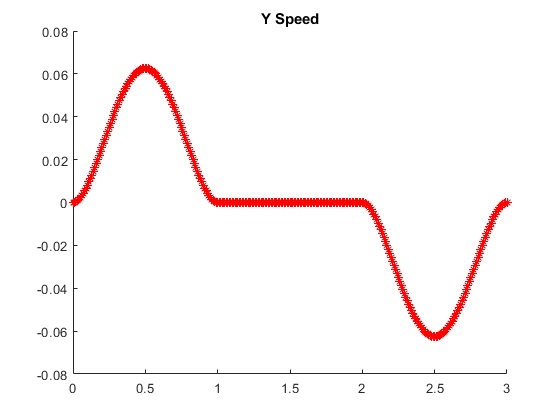

%Piecewise plot for Y Speed (is not exact, just a general plan. See traj_design_posY at the end
%for the real Y Speed plot)
hold on;
plot(time, PD, 'r*');
plot(tA_time:.01:tB_time, 0, 'r*');
plot(tB_time:.01:3, -PD, 'r*');
title('Y Speed');
hold off

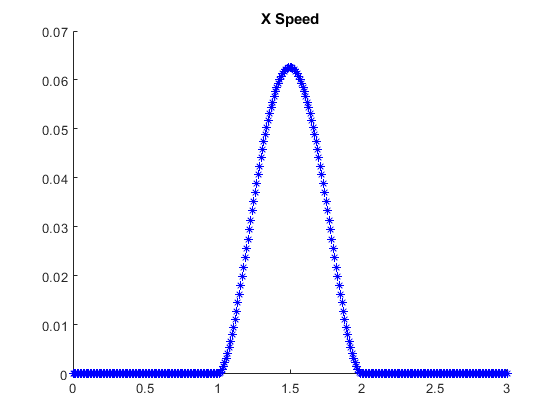

clf;
%Piecewise plot for X Speed
hold on;
plot(0:0.01:tA_time, 0, 'b*');
plot(tA_time:0.01:tB_time, PD, 'b*');
plot(tB_time:.01:3, 0, 'b*');
title('X Speed');
hold off